# run ryan4_model_incremetal_learning_data

use_test_data_1 = true

use_test_data_1 = logical
   1


use_test_data_2 = false 

use_test_data_2 = logical
   0


use_test_data_3 = false 

use_test_data_3 = logical
   0



use_y_from_observed = true 

use_y_from_observed = logical
   1


use_y_from_most_same = false

use_y_from_most_same = logical
   0


use_y_from_less_same = false 

use_y_from_less_same = logical
   0


if use_test_data_1
    ytrain = ynorm_ref
    Xtrain = xnorm_ref
    Ytrain = Y_ref
    Ytrain_soh = Y_soh_ref
end

ytrain =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


Xtrain =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010    0.0

Ytrain =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


Ytrain_soh =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464



if use_test_data_2
    ytrain = ynorm_ref_to_small2
    Xtrain = xnorm_ref_to_small2
    Ytrain = Y_ref_to_small2
    Ytrain_soh = Y_soh_ref_to_small2
end

if use_test_data_3
    ytrain = ynorm_ref_to_big2
    Xtrain = xnorm_ref_to_big2
    Ytrain = Y_ref_to_big2
    Ytrain_soh = Y_soh_ref_to_big2
end


n = numel(ytrain);
numObsPerChunk = 5;

maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

Mdl = incrementalRegressionLinear(  ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',10, ...
    'Learner','leastsquares', ...
    'Metrics',{ 'mse' })

Mdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [0×1 double]
                 Bias: 0
              Learner: 'leastsquares'


  Properties, Methods



% Preallocation
 %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    

% Incremental fitting
rng("default"); % For reproducibility
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;    
    Mdl = updateMetricsAndFit(Mdl,Xtrain(idx,:),ytrain(idx));
    Mdl.Beta;
    Mdl.Bias;
    %ei{j,:} = Mdl.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = Mdl.Metrics{"MeanSquaredError",:};
    % mae{j,:} = Mdl.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = Mdl.Beta(10);
end

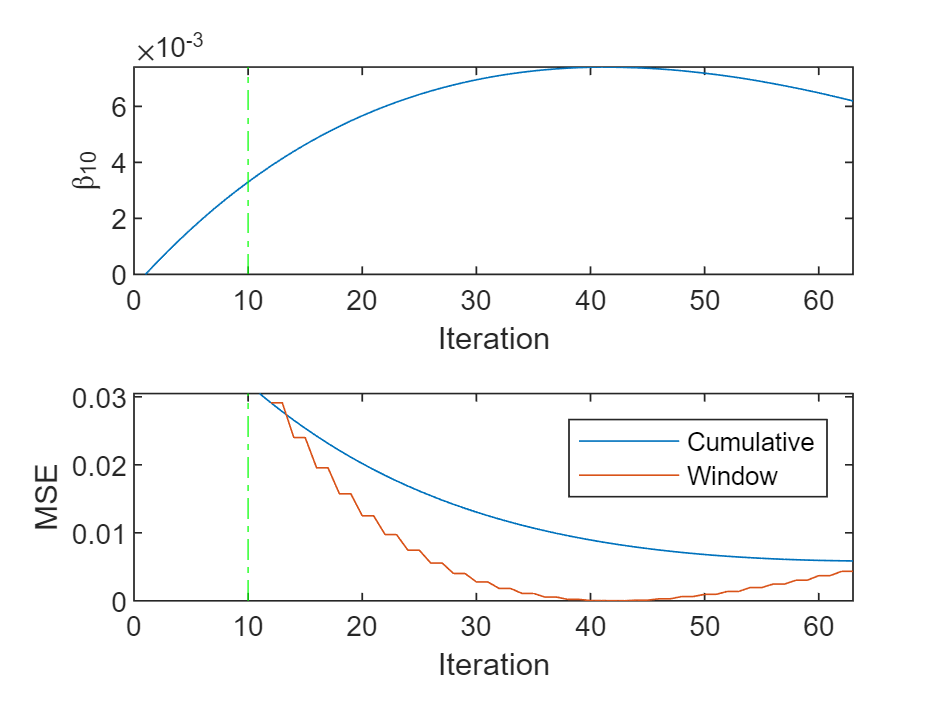

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

total = length(ytrain)

total = 315

pre = 50;
future = total - pre

future = 265

Xtrain_all = Xtrain ;
ytrain_all = ytrain ;
Ytrain_all = Ytrain ;
Ytrain_SOH_all = Ytrain_soh;

Xtrain_pre = Xtrain(1:pre,:);
ytrain_pre = ytrain(1:pre,:);
Ytrain_pre = Ytrain(1:pre,:);
Ytrain_SOH_pre = Ytrain_soh(1:pre,:);

Xtrain_future = Xtrain(pre+1:end,:);
ytrain_future = ytrain(pre+1:end,:);
Ytrain_future = Ytrain(pre+1:end,:);
Ytrain_SOH_future = Ytrain_soh(pre+1:end,:);

[Mdl1,FitInfo] = fitrlinear(Xtrain_pre,ytrain_pre,"learner","leastsquares")

Mdl1 =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: 0.2473
               Lambda: 0.0200
              Learner: 'leastsquares'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 0.0200
                 Objective: 7.4262e-05
            IterationLimit: 1000
             NumIterations: 8
              GradientNorm: 1.6935e-05
         GradientTolerance: 1.0000e-06
      RelativeChangeInBeta: 7.8861e-05
             BetaTolerance: 1.0000e-04
             DeltaGradient: []
    DeltaGradientTolerance: []
           TerminationCode: 1
         TerminationStatus: {'Tolerance on coefficients satisfied.'}
                   History: []
                   FitTime: 0.0018
                    Solver: {'bfgs'}


Mdl1.Beta

ans =    -0.0010
   -0.0008
   -0.0008
   -0.0007
   -0.0007
   -0.0006
   -0.0006
   -0.0006
   -0.0005
   -0.0004


Mdl1.Bias

ans = 0.2473

yhat_pre_calc = Xtrain_pre(1,:) * Mdl1.Beta + Mdl1.Bias

yhat_pre_calc = 0.2488

yhat_pre_predict = predict(Mdl1,Xtrain_pre(1,:))

yhat_pre_predict = 0.2488

# 시나리오 1.

yhat_pre = predict(Mdl1,Xtrain_pre);

Yhat_pre = minmax_denorm_with_param(yhat_pre,ymin_RUL,yrate_RUL);
[rmse_pre,mape_pre,ape_pre,ae_pre,err_pre] = eval_perfomance(Ytrain_pre,yhat_pre);

mape = 99.9146

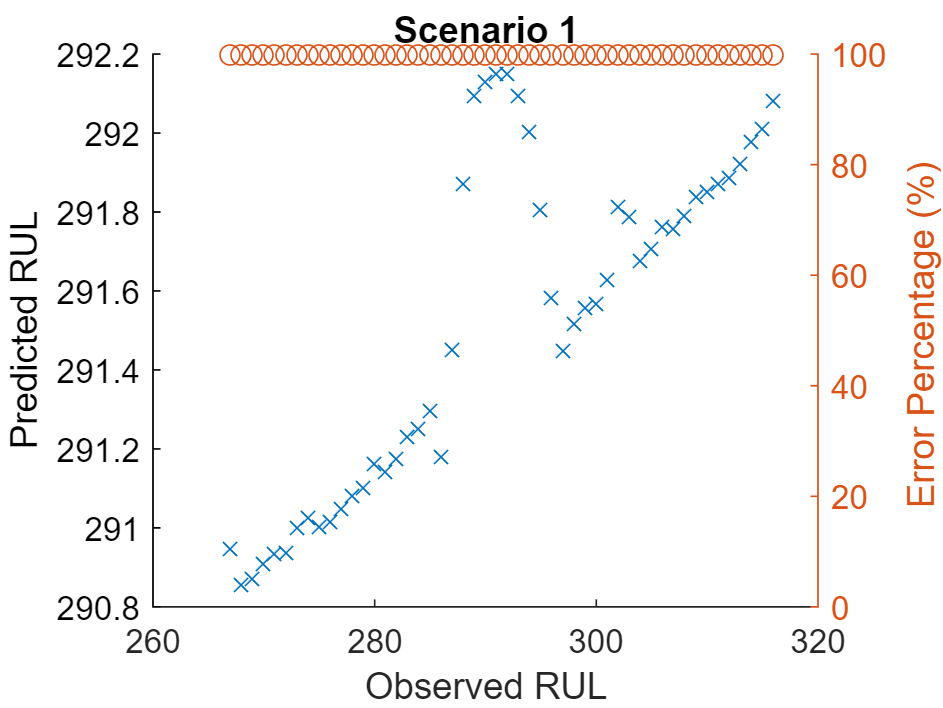

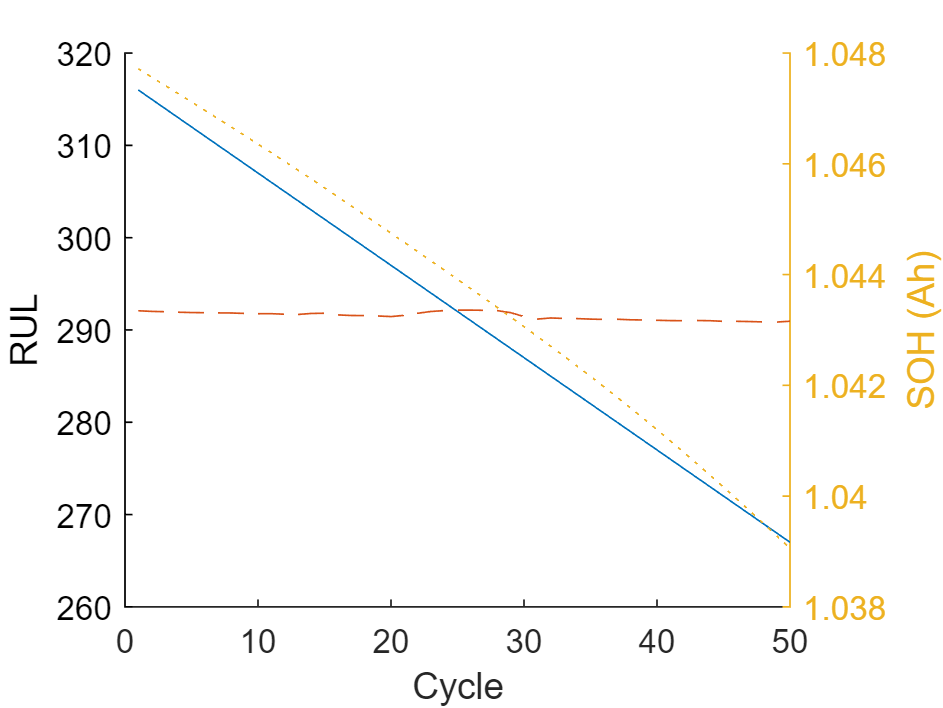

ryan4_util_plot_scenario( Ytrain_pre, Yhat_pre, ape_pre, Ytrain_SOH_pre,  'Scenario 1', false)

# 시나리오 2.

yhat_future = predict(Mdl1,Xtrain_future);

Yhat_future = minmax_denorm_with_param(yhat_future,ymin_RUL,yrate_RUL);
[rmse_future,mape_future,ape_future,ae_future,err_future] = eval_perfomance(Ytrain_future,yhat_future);

mape = 99.5281

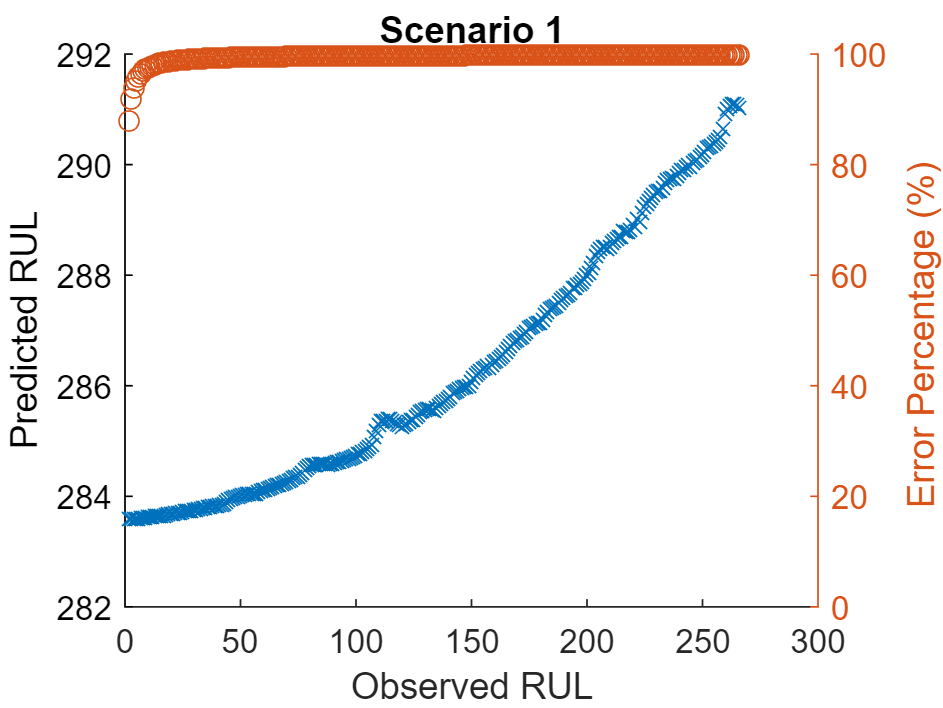

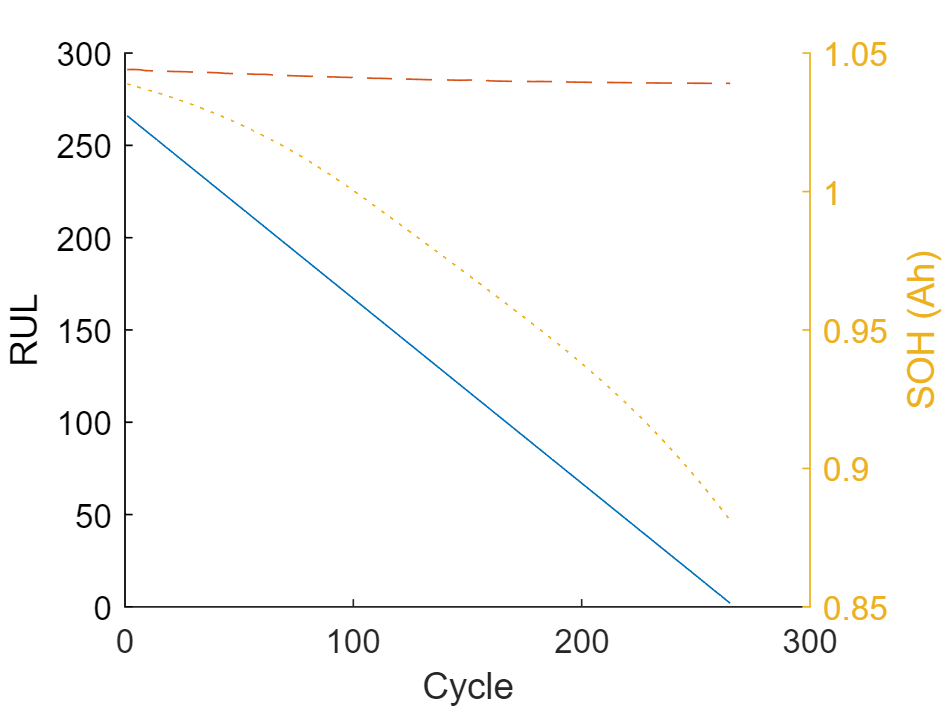

ryan4_util_plot_scenario( Ytrain_future, Yhat_future, ape_future, Ytrain_SOH_future,  'Scenario 2', false)

# 시나리오 3.

load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinregendear')


yhat_all = predict(mdl_Linear_VdRul_fitrlinear,Xtrain_all);

Yhat_all = minmax_denorm_with_param(yhat_all,ymin_RUL,yrate_RUL);
[rmse_all,mape_all,ape_all,ae_all,err_all] = eval_perfomance(Ytrain_all,yhat_all);

mape = 99.8935

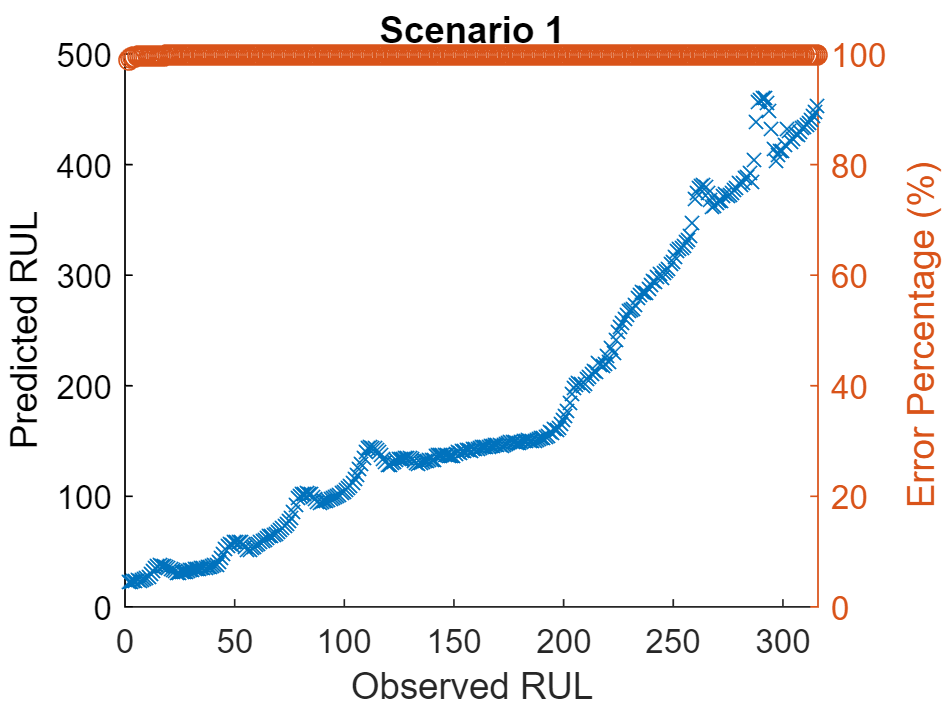

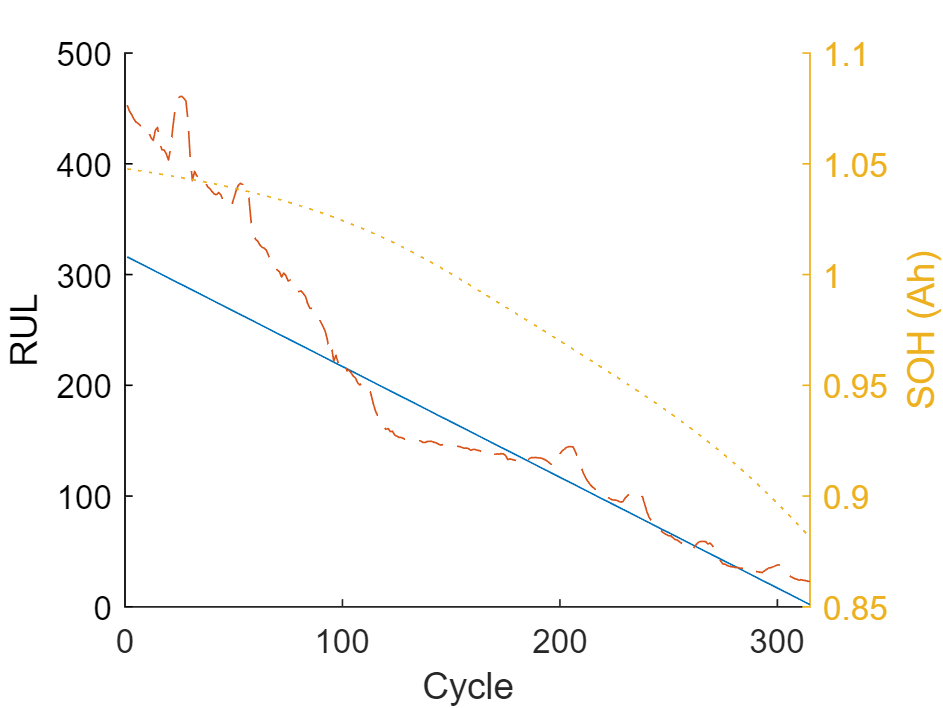

ryan4_util_plot_scenario( Ytrain_all, Yhat_all, ape_all, Ytrain_SOH_all,  'Scenario 3', false)

yhat = predict(mdl_Linear_VdRul_fitrlinear,Xtrain(1,:))

yhat = 0.3864

mdl_Linear_VdRul_fitrlinear.Beta 

ans =    -0.4300
   -0.2471
   -0.0565
    0.0360
    0.1613
    0.3305
    0.4949
    0.5662
    0.4575
    0.2428


mdl_Linear_VdRul_fitrlinear.Bias

ans = -1.0687

yhat_cals = Xtrain(1,:) * mdl_Linear_VdRul_fitrlinear.Beta  +  mdl_Linear_VdRul_fitrlinear.Bias

yhat_cals = 0.3864

## 시나리오 4..

y_predict = [];
maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);


% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc

mdl_Linear_VdRul_fitrlinear_inc =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_alldict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc.Beta' ;  

y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734


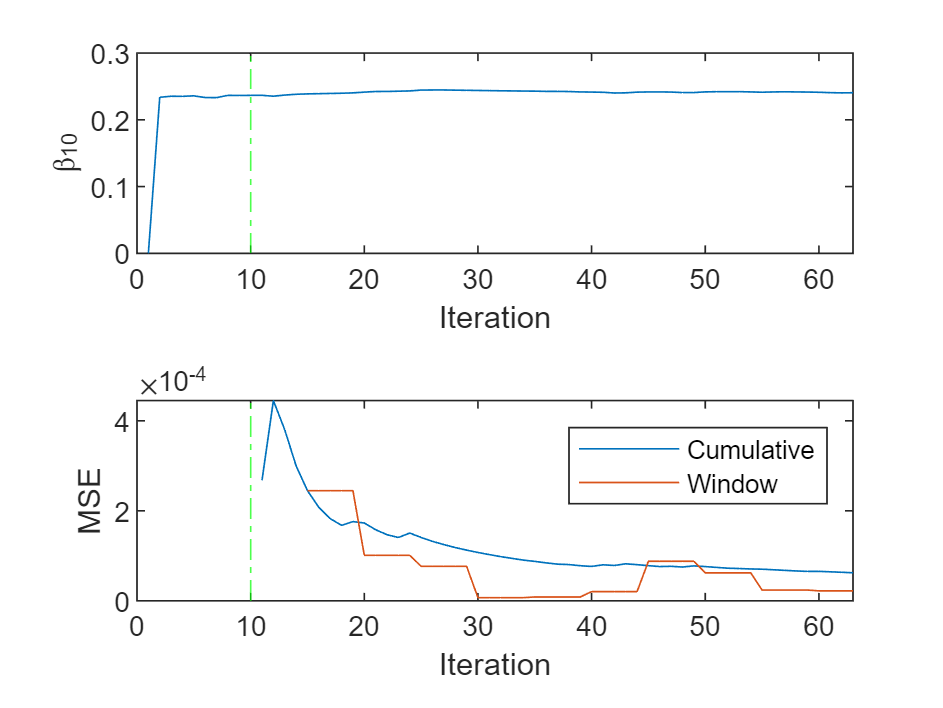



for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;  
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc = updateMetricsAndFit(...
        mdl_Linear_VdRul_fitrlinear_inc,...
        Xtrain(idx,:),...
        ytrain(idx));

    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc,Xtrain(idx,:));
    %mdl_Linear_VdRul_fitrlinear_inc.Beta' ;
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc = 5.3019

diff_percentage_all_inc = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc =     3.2686
    4.6288
    5.2595
    6.2558
    6.8528
    1.5237
    1.2473
    1.3340
    0.4798
    0.1673


diff_percentage_avg_all_inc = mean(diff_percentage_all_inc,1)

diff_percentage_avg_all_inc = 2.6769

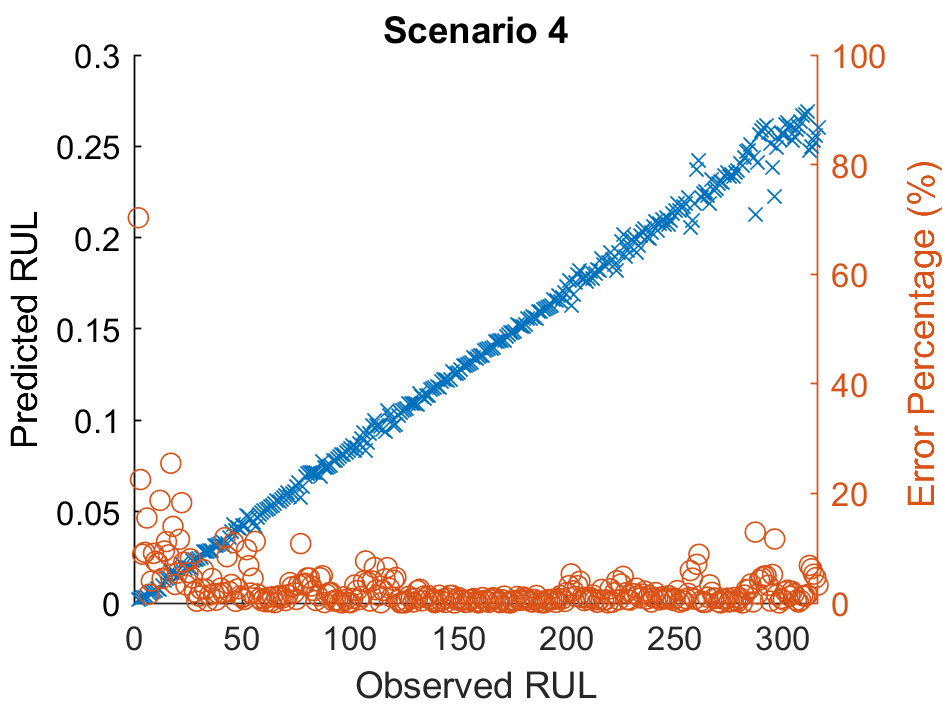

figure
hold on
plot(Ytrain_all,y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc,'o');
ylim([0 100])

hold off
title 'Scenario 4'

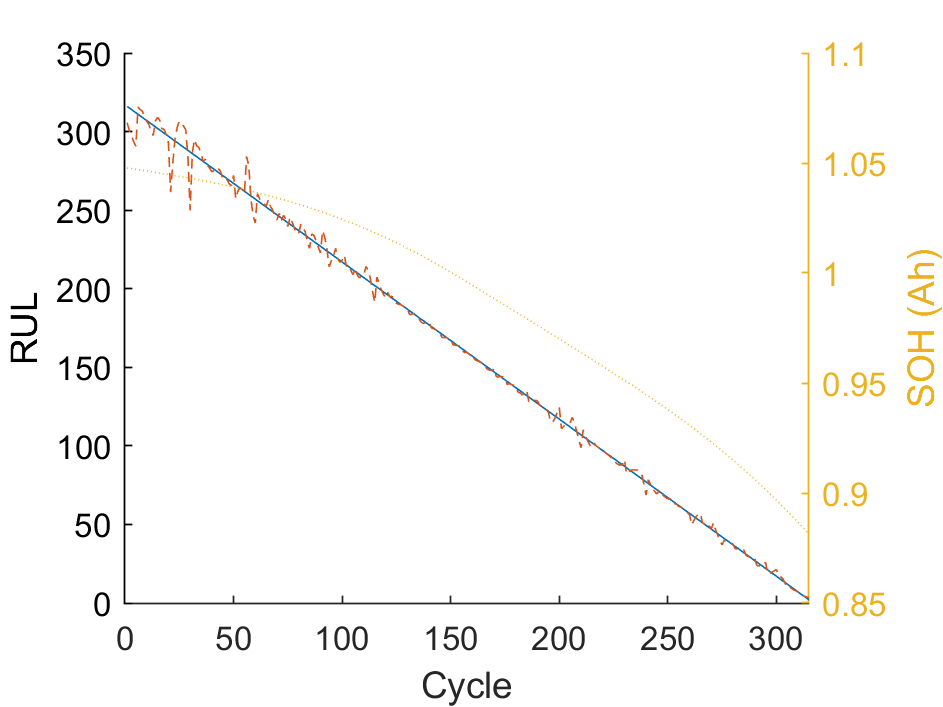


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 시나리오 5. - 학습율 0.002

y_predict = [];
maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);


mdl_Linear_VdRul_fitrlinear_inc1 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc1

mdl_Linear_VdRul_fitrlinear_inc1 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc1.Beta' ;

y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734


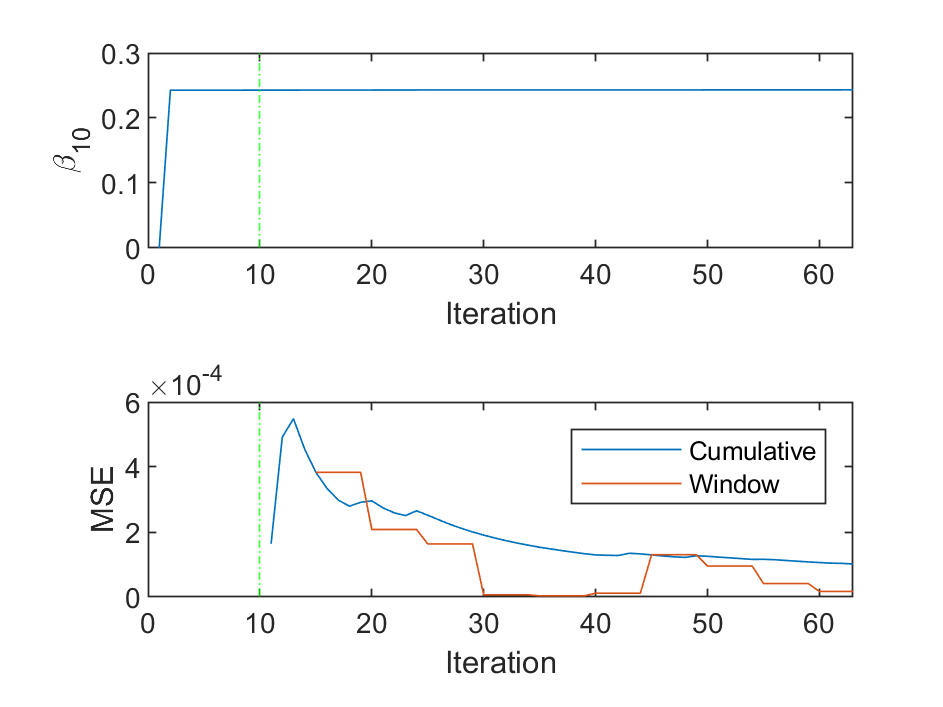


for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc1 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc1, ...
        Xtrain(idx,:), ...
        y_predict_temp); % 그래나 실제y값을 알기히들다. 
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc1.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc1.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc1,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc1 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc1 = 57.1346

diff_percentage_all_inc1 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc1 = 1.0e+03 *

    0.0434
    0.0421
    0.0416
    0.0408
    0.0403
    0.0405
    0.0403
    0.0405
    0.0398
    0.0392


diff_percentage_avg_all_inc1 = mean(diff_percentage_all_inc1,1)

diff_percentage_avg_all_inc1 = 42.0440

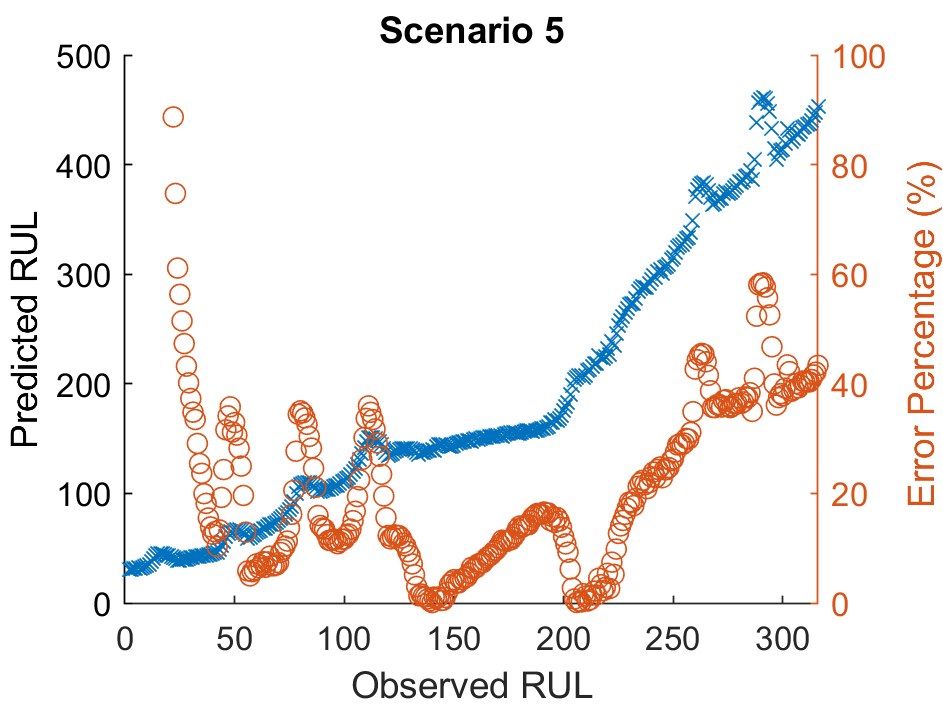

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc1,'o');
ylim([0 100])

hold off
title 'Scenario 5'

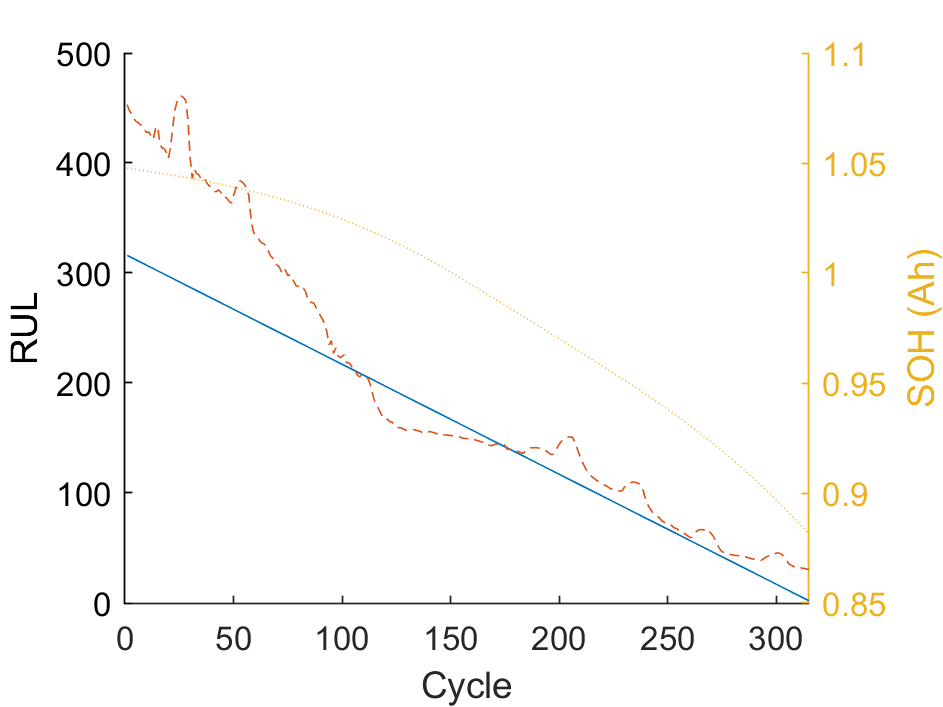


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

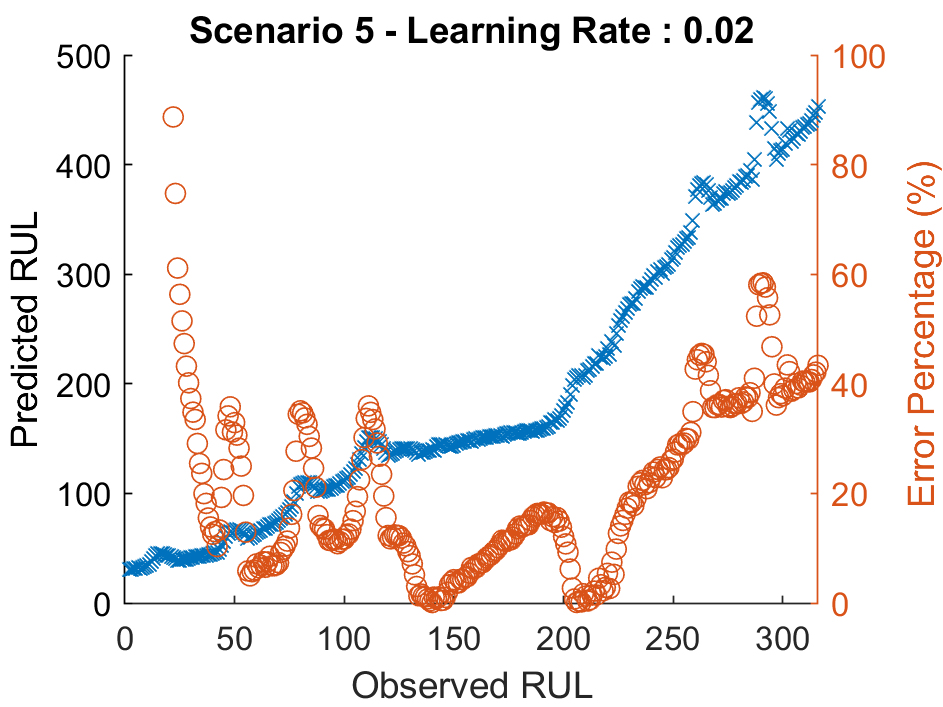



figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc1,'o');
ylim([0 100])

hold off
title 'Scenario 5 - Learning Rate : 0.02'


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 시나리오 5a . 자기가 예측한 값으로 모델 업데이트. 러닝레이트를 0.1로 테스트 = 오류증가 


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);


% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc1a = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc1a

mdl_Linear_VdRul_fitrlinear_inc1a =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


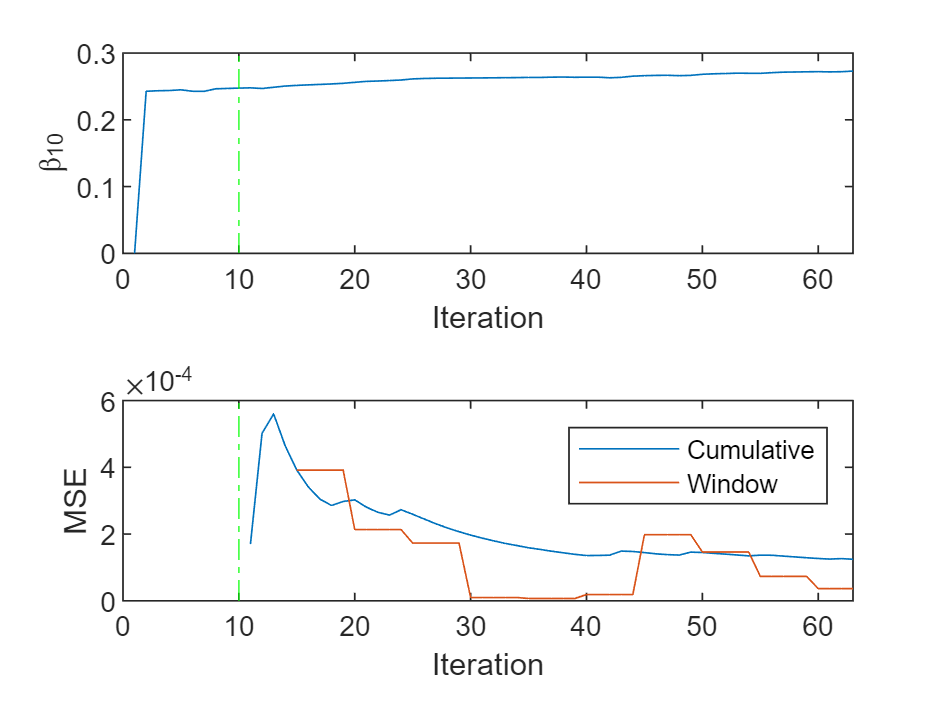

n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
% mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc1a.Beta' ;

y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1a, Xtrain(1:numObsPerChunk,:));

for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ;   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc1a = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc1a, ...
        Xtrain(idx,:), ...
        y_predict_temp); % 그래나 실제y값을 알기히들다. 
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1a,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc1a.Beta';

    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc1a.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc1a.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc1a.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc1a.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc1a.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc1a.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc1a.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc1a.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc1a,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc1a = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc1a = 316.8099

diff_percentage_all_inc1a = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc1a = 1.0e+04 *

    0.0043
    0.0042
    0.0042
    0.0041
    0.0040
    0.0045
    0.0045
    0.0045
    0.0044
    0.0044


diff_percentage_avg_all_inc1a = mean(diff_percentage_all_inc1a,1)

diff_percentage_avg_all_inc1a = 677.5441

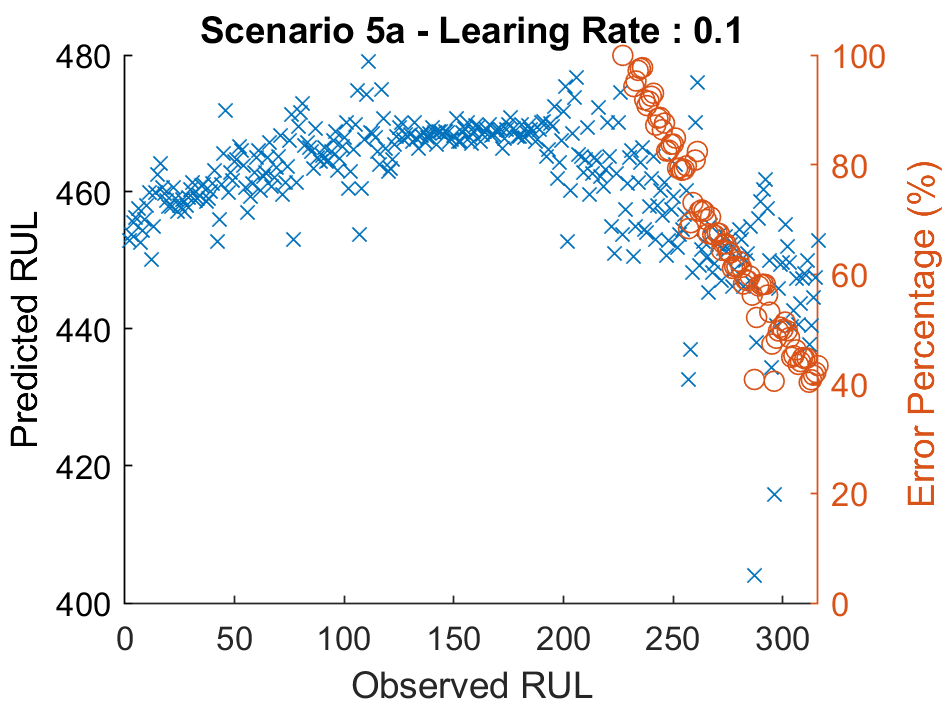

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc1a,'o');
ylim([0 100])

hold off
title 'Scenario 5a - Learing Rate : 0.1'

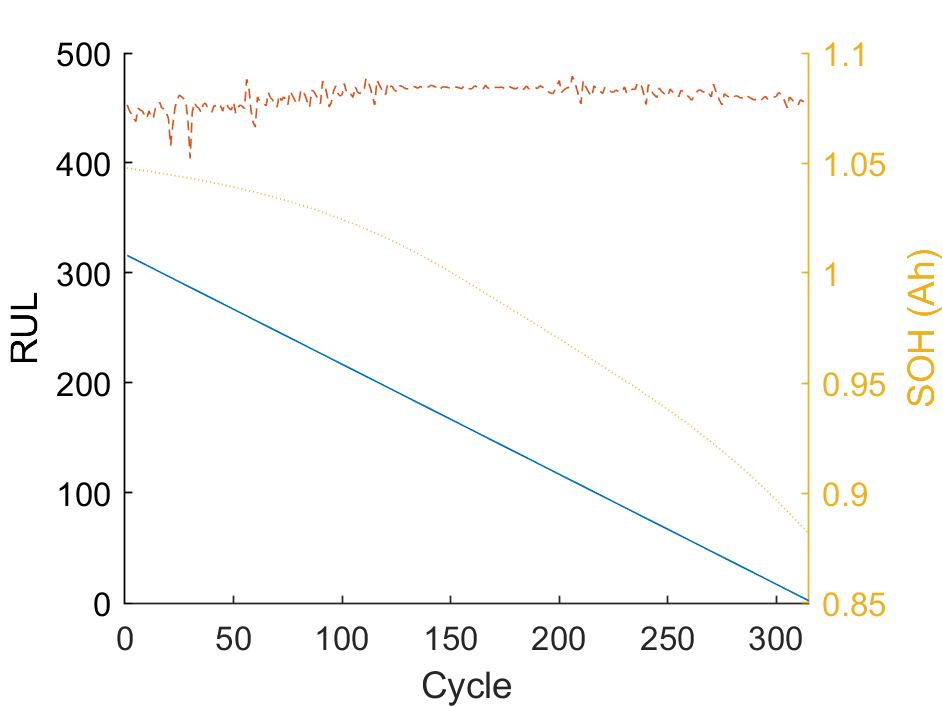


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 시나리오 6 - 'LearnRate',0.1,  - average



maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);


% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc2 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc2

mdl_Linear_VdRul_fitrlinear_inc2 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
%mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc2.Beta' ;


y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734


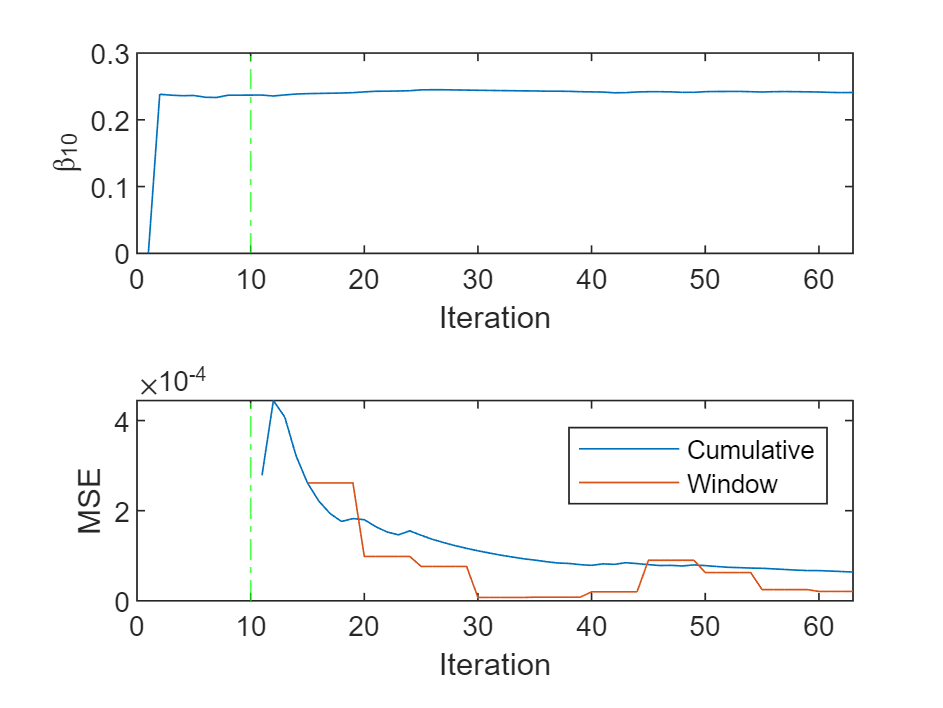



for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ; 
    % y_update = ytrain(idx);
    y_update = ( ytrain(idx) + y_predict_temp ) /2 ;

    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc2 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc2, ...
        Xtrain(idx,:), ...
        y_update); %  
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc2.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc2.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc2 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc2 = 10.9030

diff_percentage_all_inc2 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc2 =    20.0222
   18.7192
   18.1553
   17.2364
   16.7149
    9.8326
    9.5824
    9.6932
    8.8646
    8.2439


diff_percentage_avg_all_inc2 = mean(diff_percentage_all_inc2,1)

diff_percentage_avg_all_inc2 = 9.5451

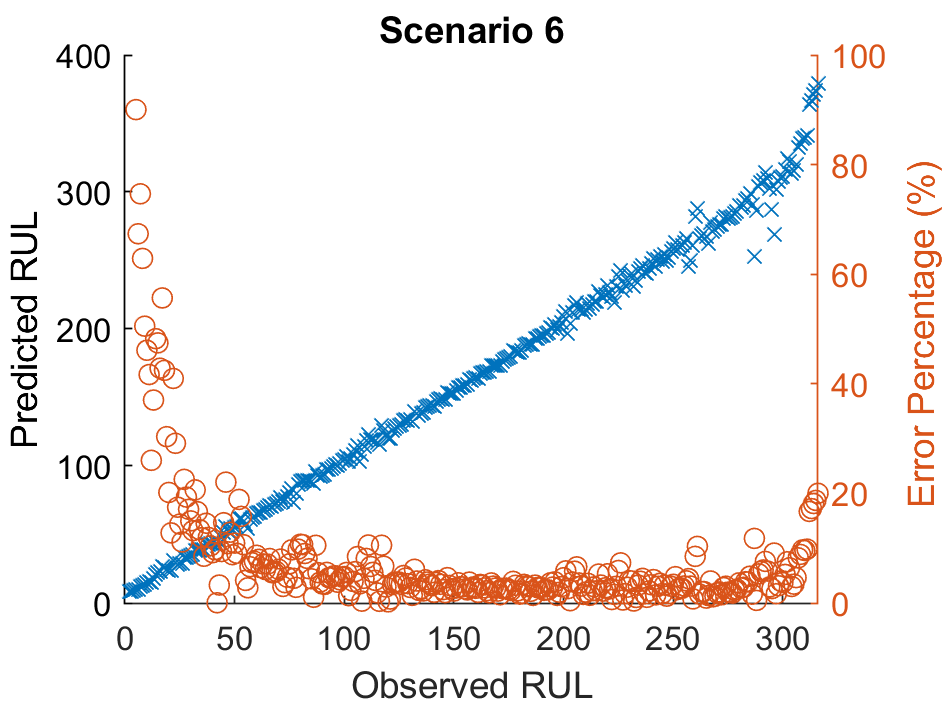

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc2,'o');
ylim([0 100])

hold off
title 'Scenario 6'

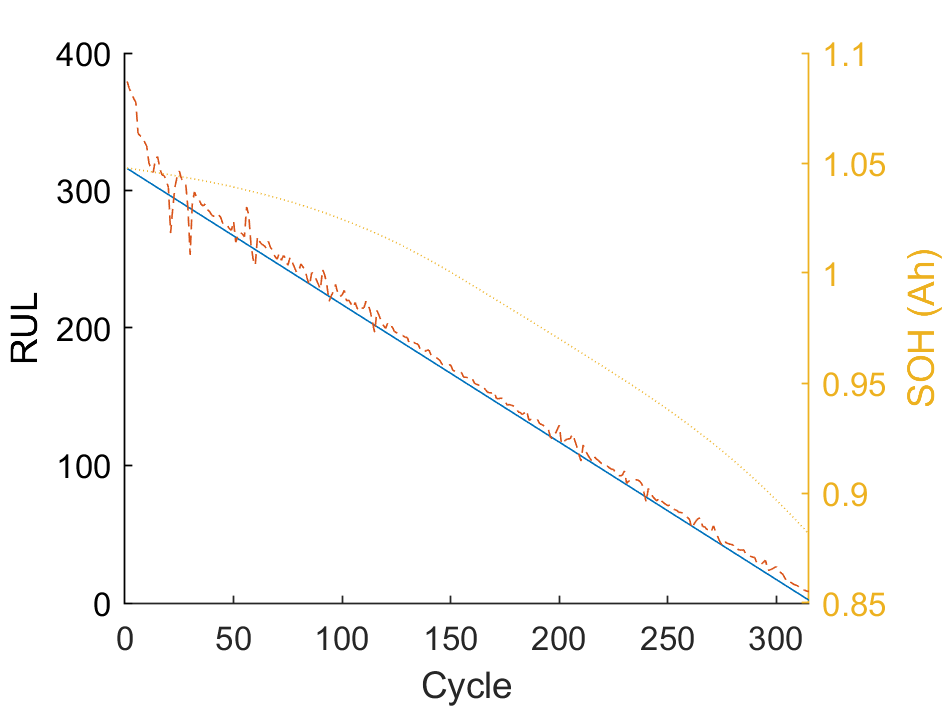



figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 시나리오 7 - 'LearnRate',0.1,  - only similar



maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);


% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc2 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' }...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc2

mdl_Linear_VdRul_fitrlinear_inc2 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [1×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
%mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc2.Beta' ;


y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734



for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend ; 
    % y_update = ytrain(idx);
    y_update = ( ytrain(idx) + y_predict_temp ) /2 ;

    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc2 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc2, ...
        Xtrain(idx,:), ...
        y_update); %  
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc2.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp] ;
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanSquaredError",:};
    %mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc2.Beta(10);
end

tiledlayout(2,1)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
% nexttile
% h = plot(ei.Variables);
% xlim([0 nchunk])
% ylabel('Epsilon Insensitive Loss')
% xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,ei.Properties.VariableNames)
% xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')

% nexttile
% h = plot(mae.Variables);
% xlim([0 nchunk])
% ylabel('MAE')
% xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
% legend(h,mae.Properties.VariableNames)
% xlabel('Iteration')

%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain_all);
%y_predict = [ y_predict ; y_predict(end)];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc2 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

Arrays have incompatible sizes for this operation.

Related documentation

diff_percentage_all_inc2 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100
diff_percentage_avg_all_inc2 = mean(diff_percentage_all_inc2,1)
figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%) ')
plot(Ytrain_all,diff_percentage_all_inc2,'o');
ylim([0 100])

hold off
title 'Scenario 6'


figure, hold on
plot(Ytrain)
plot(Y_predict,'--')
ylabel('RUL')

yyaxis right
ylabel('SOH (Ah)'), xlabel('Cycle')
plot(Ytrain_soh,':')
hold off

## 현재까지의 자기 데이타로 학습/예측 - 실제적이지 않다. - 오차 적음


result_pre_summary = table(rmse_pre,diff_percentage_avg_pre);
result_pre_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_pre_summary

## 현재까지의 자기 데이타로 학습/이후 예측 - 오차 큼


result_future_summary = table(rmse_future,diff_percentage_avg_future);
result_future_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_future_summary

## 다른 데이타들로 학습 후 자기 데이타로 예측 - 일반적 시나리오 - 오차 보통


result_all_summary = table(rmse_all,diff_percentage_avg_all);
result_all_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_summary

## 기본 모델은 클라우드에서 학습한 것. 점진적 학습. 자신의 미래 RUL을 확신하는 경우 - 오차 적음. 학습비율 크게.


result_all_inc_summary = table(rmse_all_inc,diff_percentage_avg_all_inc);
result_all_inc_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc_summary

## 확실할 수 없다. 5개의 관측으로 모델갱신 후 다음 5개 예측 - 오차 큼 - 학습비율 작게 


result_all_inc1_summary = table(rmse_all_inc1,diff_percentage_avg_all_inc1);
result_all_inc1_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc1_summary


## 확실할 수 없다. 5개의 관측으로 모델갱신 후 다음 5개 예측 - 오차 큼 - 학습비율은 그대로 0.1 


result_all_inc1a_summary = table(rmse_all_inc1a,diff_percentage_avg_all_inc1a);
result_all_inc1a_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc1a_summary

## 확실할 수 없다. 5개의 관측으로 모델갱신 후 다음 5개 예측 - 오차 큼 - 학습비율 0.01


result_all_inc1b_summary = table(rmse_all_inc1b,diff_percentage_avg_all_inc1b);
result_all_inc1b_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc1b_summary

## 5개의 예측값과 비슷한 다른 데이타의 5개 값을 이용 모델 갱신 -오차 작음


result_all_inc2_summary = table(rmse_all_inc2,diff_percentage_avg_all_inc2);
result_all_inc2_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_all_inc2_summary

% https://kr.mathworks.com/help/matlab/matlab_prog/limitations-of-tables-and-timetables.html

mape_pre       =  diff_percentage_avg_pre        ;
mape_future    =  diff_percentage_avg_future     ;
mape_all       =  diff_percentage_avg_all        ;
mape_all_inc   =  diff_percentage_avg_all_inc    ;
mape_all_inc1  =  diff_percentage_avg_all_inc1   ;
mape_all_inc2  =  diff_percentage_avg_all_inc2   ;

rmse_list = [ rmse_pre ; rmse_future ; rmse_all ; rmse_all_inc ; rmse_all_inc1 ; rmse_all_inc2 ]
mape_list = [ mape_pre ; mape_future ; mape_all ; mape_all_inc ; mape_all_inc1 ; mape_all_inc2 ]
scenario_list = ["Scenario 1" ; "Scenario 2" ;"Scenario 3";"Scenario 4";"Scenario 5";"Scenario 6"]
scenario_index_list = ["1" ; "2" ;"3";"4";"5";"6"]
RowNames = {'Scenario 1','Scenario 2','Scenario 3','Scenario 4','Scenario 5','Scenario 6'}
VariableNames = {'Scenario #','RMSE','MAPE'}
VariableNames1 = {'RMSE','MAPE'}

result_NoChange = table( scenario_list, rmse_list , mape_list , 'VariableNames',VariableNames);
result_NoChange.Properties.Description = 'Test Result : Without Patten Change';
result_NoChange.Properties
result_NoChange.Properties.RowNames = scenario_list;
result_NoChange

result_NoChange1 = table( rmse_list , mape_list , 'VariableNames',VariableNames1); %,'RowNames',RowNames)
result_NoChange1.Properties.Description = 'Test Result : Without Patten Change';
result_NoChange1.Properties.RowNames = scenario_list
result_NoChange1.Properties
result_NoChange1

performace_mape = (1 - (mape_all_inc2 / mape_all)) * 100
performace_rmse = (1 - (rmse_all_inc2 / rmse_all)) * 100



% load patients
% T = table(Gender,Age,Height,Weight,Smoker,Systolic,Diastolic)



% http://matlab.izmiran.ru/help/toolbox/nnet/model211.html


p1 = [-1  0 1 0 1 1 -1  0 -1 1 0 1];
t1 = [-1 -1 1 1 1 2  0 -1 -1 0 1 1 ];
net = linearlayer([0 1],0.1)
[net,y,e,pf] = adapt(net,p1,t1)
%clear mse
mse(e)

% https://kr.mathworks.com/matlabcentral/answers/269435-what-is-the-difference-between-the-regress-function-and-the-fitlm-function
% The key difference is intercept: 1. "fitlm(x,y)" function uses intercept by default 2. "regress(y,x)" function uses no intercept by default (you can add intercept by adding "ones" matrix)

% https://kr.mathworks.com/help/stats/fitrlinear.html
% fitrlinear
% Fit linear regression model to high-dimensional data


%Alternatives for Lower-Dimensional Data
%High-dimensional linear classification and regression models minimize objective functions relatively quickly, but at the cost of some accuracy, the numeric-only predictor variables restriction, and the model must be linear with respect to the parameters. If your predictor data set is low- through medium-dimensional, or contains heterogeneous variables, then you should use the appropriate classification or regression fitting function. To help you decide which fitting function is appropriate for your low-dimensional data set, use this table.

% Model to Fit	Function	Notable Algorithmic Differences
% SVM	
% Binary classification: fitcsvm
% 
% Multiclass classification: fitcecoc
% 
% Regression: fitrsvm
% 
% Computes the Gram matrix of the predictor variables, which is convenient for nonlinear kernel transformations.
% 
% Solves dual problem using SMO, ISDA, or L1 minimization via quadratic programming using quadprog (Optimization Toolbox).
% 
% Linear regression	
% Least-squares without regularization: fitlm
% 
% Regularized least-squares using a lasso penalty: lasso
% 
% Ridge regression: ridge or lasso
% 
% lasso implements cyclic coordinate descent.
% 
% Logistic regression	
% Logistic regression without regularization: fitglm.
% 
% Regularized logistic regression using a lasso penalty: lassoglm
% 
% fitglm implements iteratively reweighted least squares.
% 
% lassoglm implements cyclic coordinate descent.



% https://kr.mathworks.com/help/stats/incrementalregressionlinear.html
% Description
% incrementalRegressionLinear creates an incrementalRegressionLinear model object, which represents an incremental linear model for regression problems. Supported learners include support vector machine (SVM) and least squares.
% 
% Unlike other Statistics and Machine Learning Toolbox™ model objects, incrementalRegressionLinear can be called directly. Also, you can specify learning options, such as performance metrics configurations, parameter values, and the objective solver, before fitting the model to data. After you create an incrementalRegressionLinear object, it is prepared for incremental learning.
% 
% incrementalRegressionLinear is best suited for incremental learning. For a traditional approach to training an SVM or linear regression model (such as creating a model by fitting it to data, performing cross-validation, tuning hyperparameters, and so on), see fitrsvm or fitrlinear.
% 
% 
% https://kr.mathworks.com/help/stats/regressionlinear-class.html
% Construction
% Create a RegressionLinear object by using fitrlinear.

% codegen common file
gen_code = false

load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')

cfg = coder.config('lib','ecoder',false);
cfg.GenCodeOnly = true;
cfg.HardwareImplementation.ProdHWDeviceType = 'ARM Compatible->ARM Cortex';


Xtrain_one_sample = Xtrain(1,:)

predictorData = coder.typeof(Xtrain(1:5,:)); 
responseData = coder.typeof(ytrain(1:5));
observedData = coder.typeof(ytrain(1:5));



if gen_code
scenario_12_Mdl = Mdl1
%saveLearnerForCoder(scenario_12_Mdl,'scenario_12_Mdl');
saveLearnerForCoder(scenario_12_Mdl,'InitialLinearMdl');

configurer12 = learnerCoderConfigurer(scenario_12_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')
%configurer12.OutputFileName = 'scenario_12_Mdl'
generateCode(configurer12,cfg,'OutputPath','scenario_12_Mdl')
end

% at first, please delete existing root folder, to delete already generated
%  m files.

if gen_code
mdl_Linear_VdRul_fitrlinear.Beta
scenario_3_Mdl = mdl_Linear_VdRul_fitrlinear
saveLearnerForCoder(scenario_3_Mdl,'InitialLinearMdl');
configurer3 = learnerCoderConfigurer(scenario_3_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')
generateCode(configurer3,cfg,'OutputPath','scenario_3_Mdl')
end

if 0

scenario_6_Mdl = mdl_Linear_VdRul_fitrlinear_inc2;

saveLearnerForCoder(scenario_6_Mdl,'scenario_6_Mdl');

IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

codegen -config cfg  -d scenario_6_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report

end


if gen_code
%load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')

scenario_4_Mdl = mdl_Linear_VdRul_fitrlinear_inc
scenario_5_Mdl = mdl_Linear_VdRul_fitrlinear_inc1
scenario_5a_Mdl = mdl_Linear_VdRul_fitrlinear_inc1a
scenario_6_Mdl = mdl_Linear_VdRul_fitrlinear_inc2
end

if gen_code 
 saveLearnerForCoder(scenario_4_Mdl,'scenario_4_Mdl');
 saveLearnerForCoder(scenario_5_Mdl,'scenario_5_Mdl');
 saveLearnerForCoder(scenario_5a_Mdl,'scenario_5a_Mdl');
 saveLearnerForCoder(scenario_6_Mdl,'scenario_6_Mdl');
end
 

% https://kr.mathworks.com/help/stats/classreg.learning.coder.config.svm.classificationsvmcoderconfigurer.generatecode.html
%cfg.CustomFileNameStr = 'sc3';

% configurer4 = learnerCoderConfigurer(scenario_4_Mdl,Xtrain_one_sample) %,'ObservationsIn','columns')
% configurer4.OutputFileName = 'scenario_4_Mdl'
% generateCode(configurer4,cfg,'OutputPath','scenario_4_Mdl')

if gen_code


IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
codegen -config cfg  -d scenario_4_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

if gen_code
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
codegen -config cfg  -d scenario_5_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

if gen_code
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

% change IncrementalMdl to scenario_4_Mdl from myInitialModelIncrLearn.m 
% copy m files to current dir
codegen -config cfg  -d scenario_6_Mdl  ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsAndFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} ...
 -report
end

거의 다 했다. 

- 된것 

- 매트랩에서 시뮬레이션 한것.

- 안된것 